# Simulación de Sistemas Eléctricos

# Actividad 8: Modelo de predicción con una Var. 

- **Variable independiente (x): Energía, Voltaje......,etc. en t=t0 (Valor actual)**

- **Variable dependiente (f(x)): Energía en t=to+dt (Valor siguiente); dt=1seg**

- **Frecuencia de muestreo de los datos: 1 muestra por segundo (sps)**

- **Venta temporal de predicción: (dt=1día)**

Nombres:

- Estudiante 1: VA

- Estudiante 2: VA

Contenido:

- Descargar datos (.csv) desde desde repositorio (DataPort)

- **Paper: **[https://doi.org/10.1016/j.procs.2022.07.035](https://doi.org/10.1016/j.procs.2022.07.035)

- **Dataset:** [https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset)

- **Codigo Matlab:** [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- **Funciones de Matlab:** [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

# Preprocesamiento (*)

- **1.- Leer el archivo .csv usando Matlab y graficar los datos**

- **2.- Cambiar la frecuencia de muestreo de los datos (1 muestra por dia)**

- **3.- Adecuador el dataset con la var. independiente (x) y la var. dependiente f(x)**

# Extracción de características (*)

- **Pendiente**

# Selección de características

- **Pendiente**

# Modelo de predicción

- **4.- Dataset de training (70%) y testing (30%)**

- **5.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

- **6.- Seleccionar el modelo que tiene un menor error de predicción**

- **7.- Exportar la función del mejor modelo**

- **8.- Calcular el error de predicción usando el dataset de testing**

- **Nota: realizar la prediccion en Minutos y horas <-------------------------------------- Tarea**

- **(*) Despues:**

-     Usar la matriz de correlación para eliminar del dataset var. redundantes    

-     Filtrar datos (preprocesamiento)

-     Invrementar las características temporales

#### **Eliminar datos de memoria y command window**

clear; %Borrar el korspace
clc; %Borrar el command window

#### Configuración de carpeta /src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

**Configuranción de carpeta de /data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');
filenames=FindCSV(datapath);

# **1.- Leer el archivo .csv usando Matlab y graficar los datos**

%Esto es lo que se hace con datos .csv
data=readtable(fullfile(datapath,filenames(1).name));
%clear dataRaw; %Borrar de memoria la variable que no usare despues
%Seleccionar las variables electricas de interes
data2=table2array(data(:,1:6)); % Convertir datos de string a float o int
data2(isnan(data2))=0; % Eliminar los datos NaN


#### Graficar todas las Variables

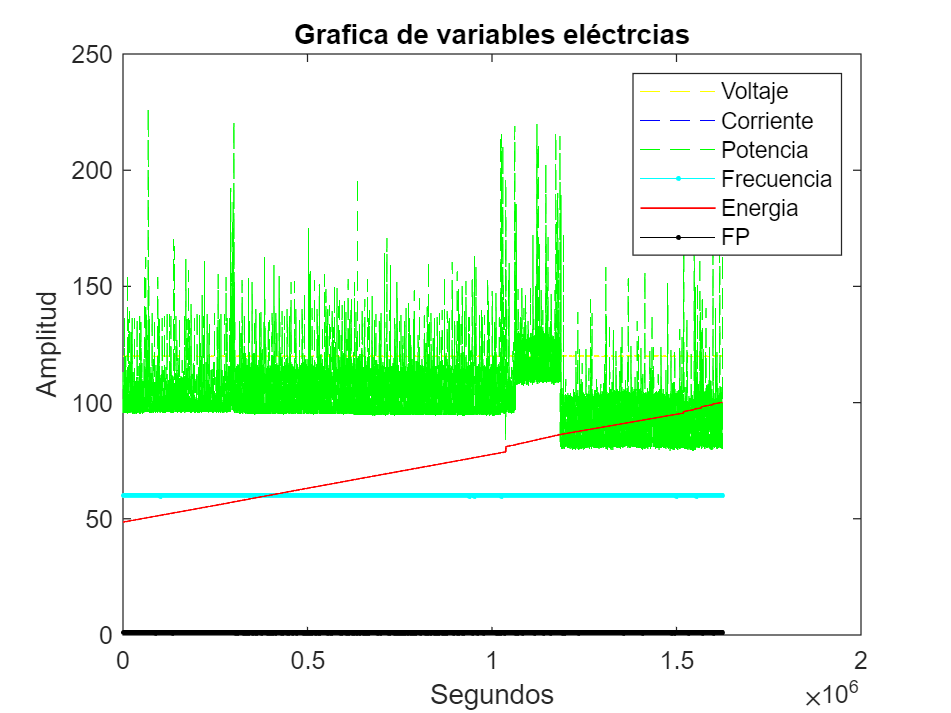

Voltaje=data2(:,1);
Corriente=data2(:,2);
Potencia=data2(:,3);
Frecuencia=data2(:,4);
Energia=data2(:,5);
FP=data2(:,6);

figure %crear una nueva grafica
%plot(data2) %plotea la grafica 1
plot(Voltaje,'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(Corriente,'b--',LineWidth=0.1);
plot(Potencia,'g--',LineWidth=0.01);
plot(Frecuencia,'c.-',LineWidth=0.1);
plot(Energia,'r',LineWidth=0.7);
plot(FP,'k.-',LineWidth=0.1);
hold off


title('Grafica de variables eléctrcias');
xlabel('Segundos');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

%Limpiar del workspace variables no utilizadas
clear data; clear datapath;

# **2.- Cambiar la frecuencia de muestreo de los datos (1 muestra por dia)**

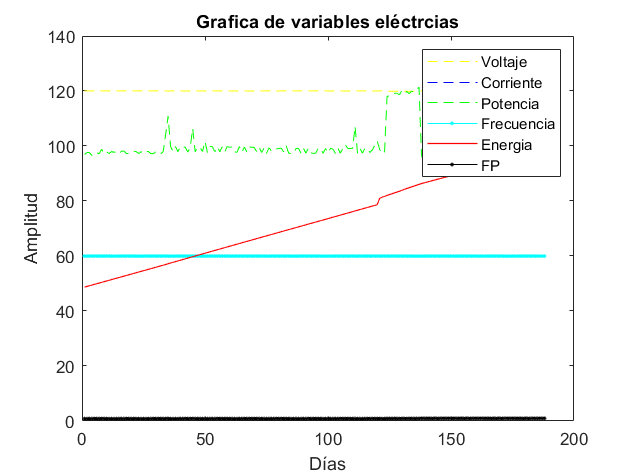

win=360*24; %dado a que los datos estan en segundos y queremos llevarlo a dias
data2Mean=fData_MeanWin(data2,win);%60 segundos 

figure %crear una nueva grafica
plot(data2Mean(:,1),'y--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(data2Mean(:,2),'b--',LineWidth=0.1);
plot(data2Mean(:,3),'g--',LineWidth=0.01);
plot(data2Mean(:,4),'c.-',LineWidth=0.1);
plot(data2Mean(:,5),'r',LineWidth=0.7);
plot(data2Mean(:,6),'k.-',LineWidth=0.1);
hold off


title('Grafica de variables eléctrcias');
xlabel('Días');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

%Limpiar del workspace variables no utilizadas
clear data2; clear FP; clear Potencia; clear Frecuencia; clear Energia;
 clear Corriente;clear Voltaje;clear win;

# **3.- Adecuador el dataset con la var. independiente (x) y la var. dependiente f(x)**

**Variables independiente (x): Energía, Voltaje......,etc. en t=t0 (Valor actual)**

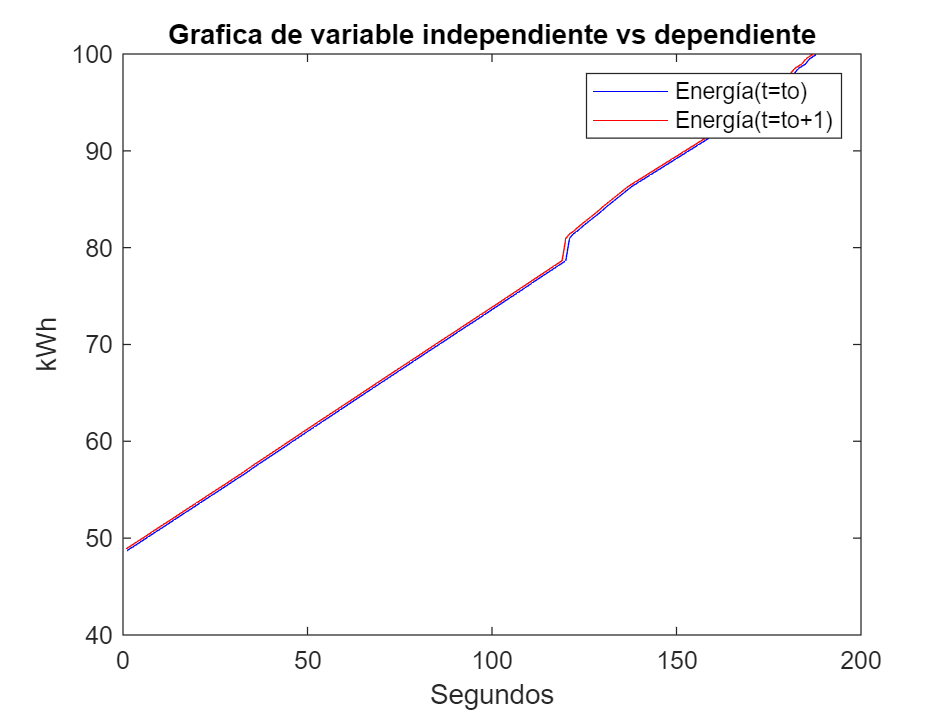

Voltaje=data2Mean(:,1);
Corriente=data2Mean(:,2);
Potencia=data2Mean(:,3);
Frecuencia=data2Mean(:,4);
Energia=data2Mean(:,5);
FP=data2Mean(:,6);
 
 % Variables independientes (x1,....,xn)
%input=[Voltaje(1:size(Voltaje,1)-1,1) Corriente(1:size(Corriente,1)-1,1)...
%    Potencia(1:size(Potencia,1)-1,1) Frecuencia(1:size(Frecuencia,1)-1,1)...
%    Energia(1:size(Energia,1)-1,1) FP(1:size(FP,1)-1,1)];
input=[Energia(1:size(Energia,1)-1,1)];
output=Energia(2:size(Energia,1),1);% Variable dependient f(x)

%Primeras columnas son las entradas o varianles independientes
%La ultima columna es la salida o variable dependiente
dataset=[input output];

 figure %crear una nueva grafica
 plot(Energia(:,1),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(output(:,1),'r',LineWidth=0.1);
 hold off
% 
 title('Grafica de variable independiente vs dependiente');
 xlabel('Segundos');
 ylabel('kWh');
 legend('Energía(t=to)','Energía(t=to+1)');

 %Limpiar del workspace variables no utilizadas
clear FP; clear Potencia; clear Frecuencia; clear Energia;
clear Corriente;clear Voltaje; clear data2Mean;
clear input; clear output;

# **4.- Dataset de training (70%) y testing (30%)**

%70 de entrenamiento y 30% de testing
Training=dataset(1:round(size(dataset,1)*0.7),:);% fila 1 hasta la fila del 70% de todas las filas
%desde la fila del 70% de todas las filas hasta la ultima fila
Testing=dataset(round(size(dataset,1)*0.7)+1:round(size(dataset,1)),:);

# **5.- ToolBox de Matlab - Regression Learner (24 algoritmos)**

regressionLearner

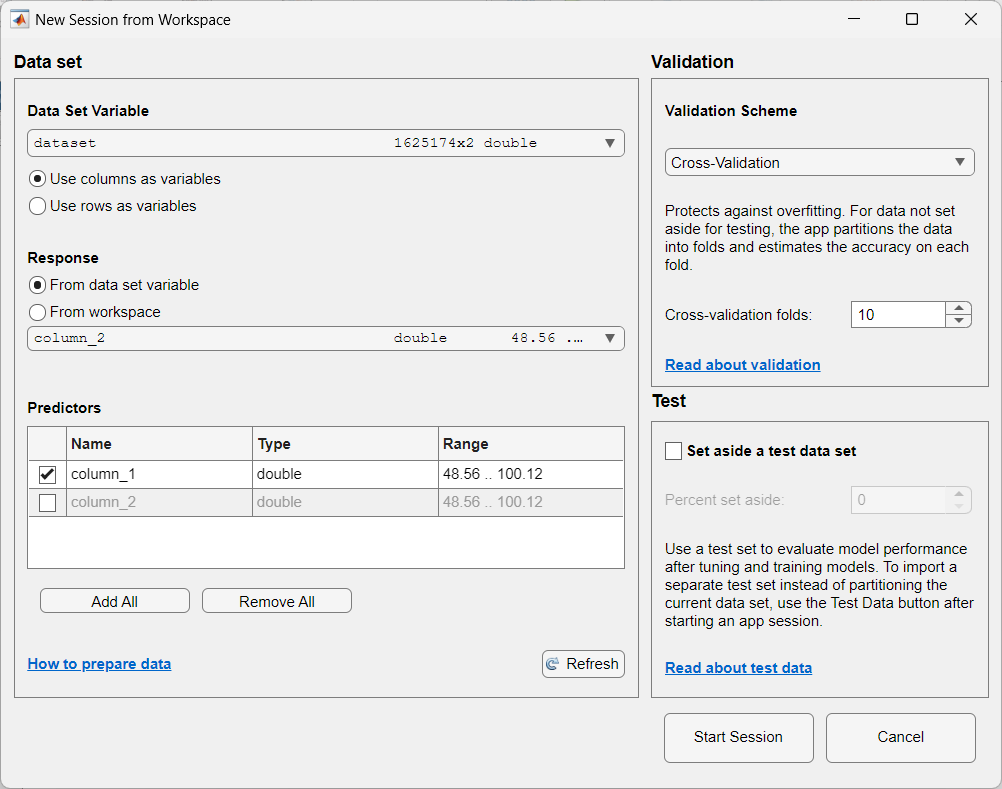

# **6.- Seleccionar el modelo que tiene un menor error de predicción**

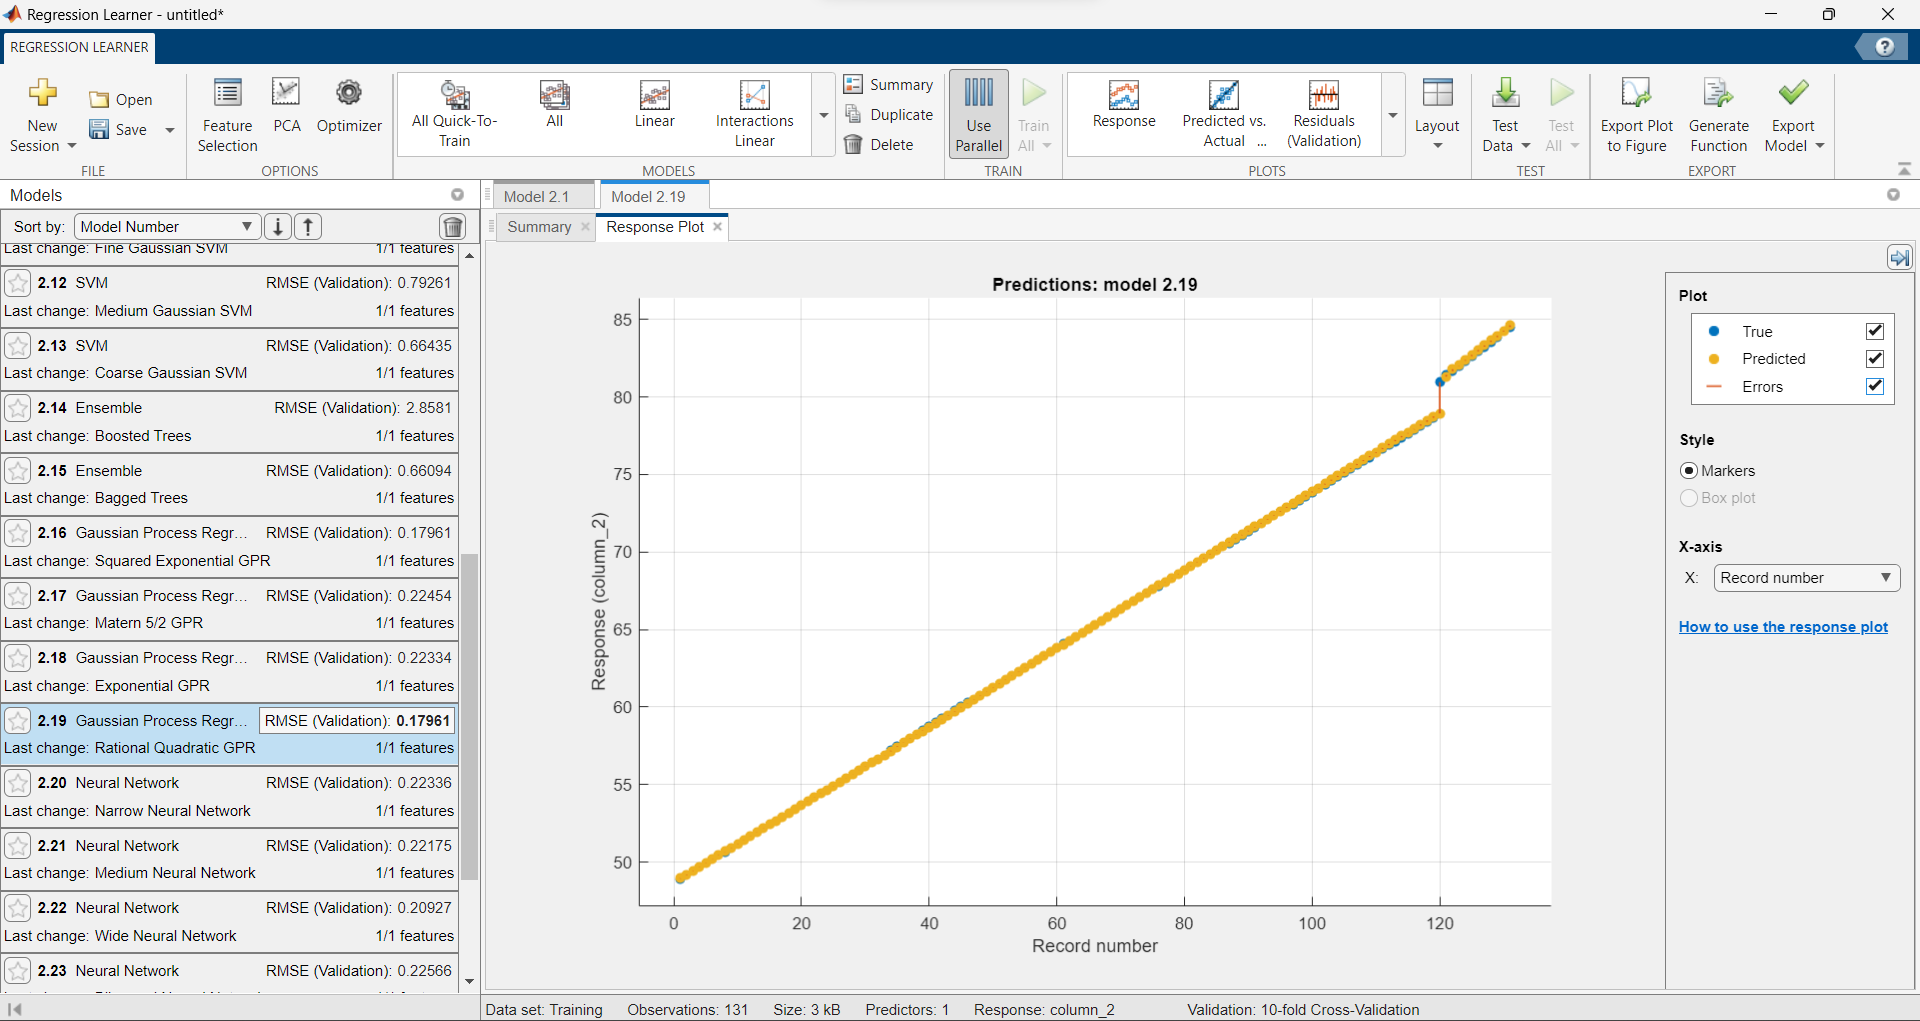

# **7.- Exportar la función del mejor modelo**

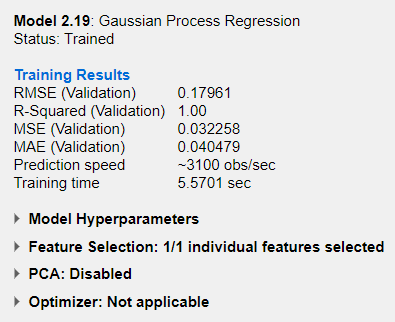

%Gaussian Process Regression
[trainedModel, validationRMSE] = trainRegressionModel(Training)

trainedModel = struct with fields:
      predictFcn: @(x)gpPredictFcn(predictorExtractionFcn(x))
    RegressionGP: [1×1 RegressionGP]
           About: 'This struct is a trained model exported from Regression Learner R2022a.'
    HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 1 columns because this model was trained using 1 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 0.1797

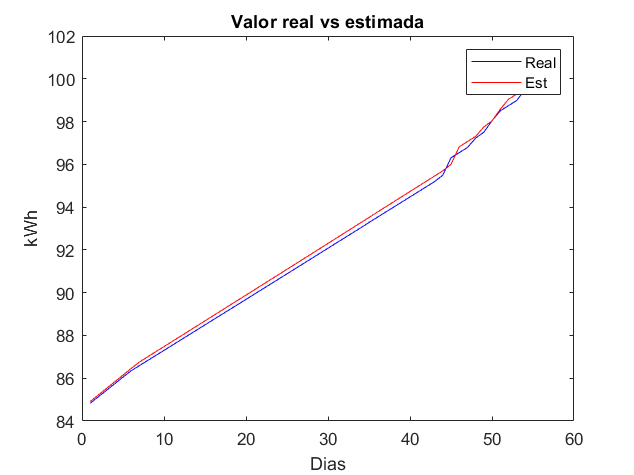

%Aqui le datos al modelo solo las varibles de entrada
EnergiaEst=trainedModel.predictFcn(Testing(:,1));

 figure %crear una nueva grafica
 plot(Testing(:,2),'b',LineWidth=0.1);
 hold on %habilita plotear mas de una grafica en la misma figura
 plot(EnergiaEst,'r',LineWidth=0.1);
 hold off
% 
 title('Valor real vs estimada');
 xlabel('Dias');
 ylabel('kWh');
 legend('Real','Est');

# **8.- Calcular el error de predicción usando el dataset de testing**

%[rmse,mse,mae] = fBar_RmseMseMae(EnergiaEst,Testing(:,2))
rmse = sqrt(immse(EnergiaEst,Testing(:,2)))

rmse = 0.2103

mse = immse(EnergiaEst,Testing(:,2))

mse = 0.0442

mae = sum(abs(EnergiaEst-Testing(:,2))/length(EnergiaEst))

mae = 0.1988